clear all; close all; clc

syms z r theta


T_0_1 = [1 0 0 0;
         0 1 0 0;
         0 0 1 z;
         0 0 0 1]

$$T\_0\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_1_2 = [cos(theta), -sin(theta), 0, 0;
         sin(theta),  cos(theta), 0, 0;
         0         ,  0         , 1, 0;
         0         ,  0         , 0, 1]

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_2_3 = [1 0 0 r;
         0 1 0 0;
         0 0 1 0;
         0 0 0 1]

$$T\_2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & r\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## requirement 1: visualize forward kinematics via input

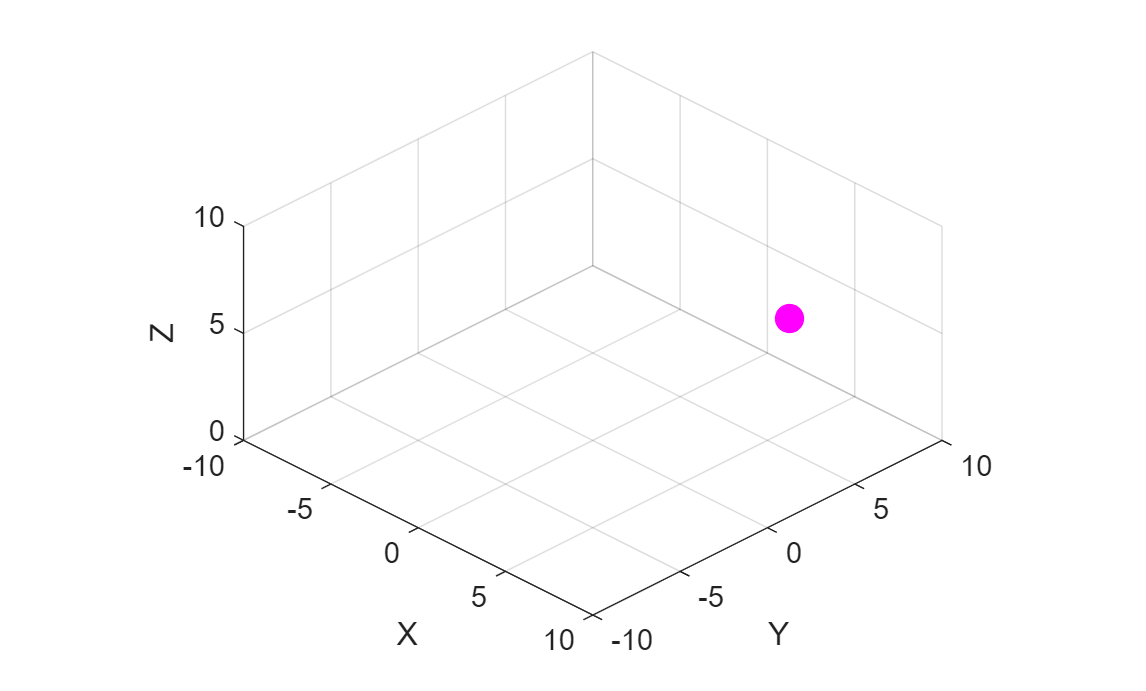

figure

% this is separate, just confirming that our transformation matrices above
% work. 
%T_total = T_0_1 * T_1_2 * T_2_3
%T_eval = subs(T_total, {z, theta, r}, {6, 7, 8})
%pf = T_eval*[0;0;0;1]
%scatter3(pf(1), pf(2), pf(3), 'LineWidth', 5)
%hold on



% the inputs are the joint variables z, Theta, r. 
plot_robot(6,7,8)

drawnow

% This function takes the joint variables and plots the resulting pose. 
function plot_robot(z, theta, r)


    % Joint positions
    O0 = [0; 0; 0];          % Base
    O1 = [0; 0; z];          % After prismatic Z
    O2 = [0; 0; z];          % Rotation happens here
    O3 = [r*cos(theta); r*sin(theta); z]; % End effector

    % Plot links
    plot3([O0(1) O1(1)], [O0(2) O1(2)], [O0(3) O1(3)], 'k', 'LineWidth', 3); 
    plot3([O2(1) O3(1)], [O2(2) O3(2)], [O2(3) O3(3)], 'b', 'LineWidth', 3);

    % Plot joints
    scatter3(O0(1),O0(2),O0(3),80,'filled','r')
    scatter3(O1(1),O1(2),O1(3),80,'filled','g')
    scatter3(O3(1),O3(2),O3(3),100,'filled','m')

    % Plot settings
    axis equal
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    xlim([-10 10])
    ylim([-10 10])
    zlim([0 10])
    view(45,30)
    hold off
    
end


## requirement 2: loop through all reachable positions

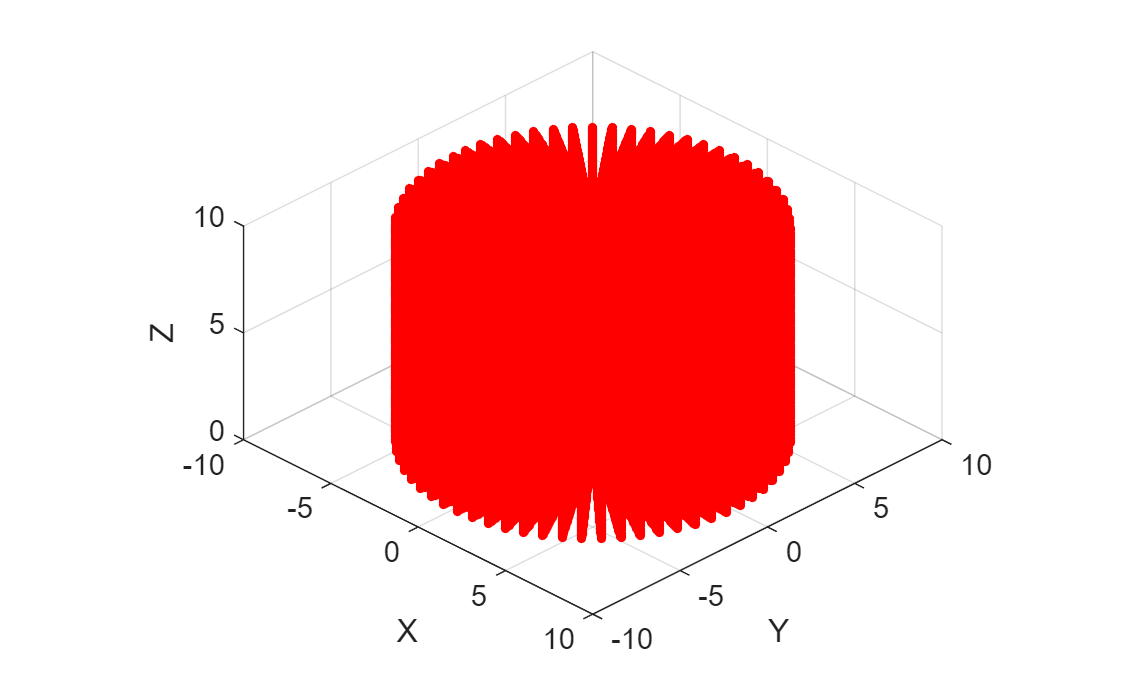

figure
axis equal
grid on
xlabel('X')
ylabel('Y')
zlabel('Z')
xlim([-10 10])
ylim([-10 10])
zlim([0 10])
view(45,30)
hold on

% this program goes in intervals of 0.1, so our computers don't
% crash. 

%limits for each joint variable     
theta = -pi:0.1:pi;
r = 2:0.1:8;
z = 0:0.1:10;
[Theta, R, Z] = meshgrid(theta, r, z);

% cylindrical to cartesian coordinates. 
X = R .* cos(Theta);
Y = R .* sin(Theta);

scatter3(X(:), Y(:), Z(:), 10, 'r', 'filled')

## requirement 3: cleaner visualization of work envelope

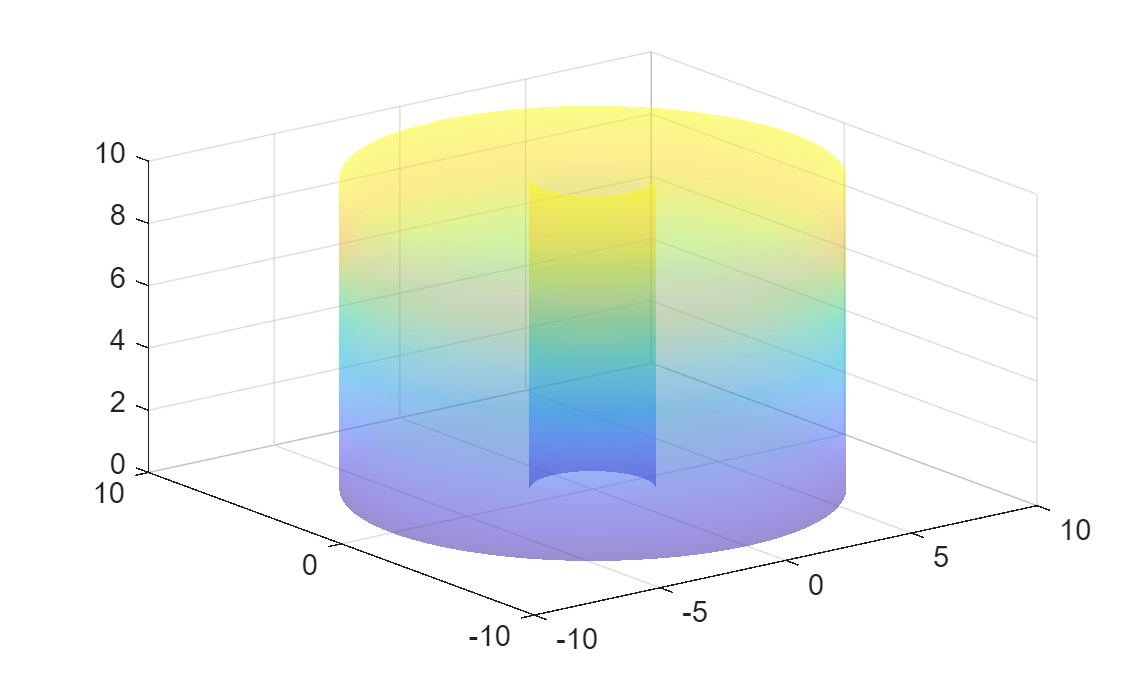

%This program also plots the work envelope, but in a cleaner way using just
%surfaces. 

figure
theta = linspace(-pi, pi, 100);
z = linspace(0, 10, 100);
[Theta, Z] = meshgrid(theta, z);

%cylindrical to cartesian coordinates
R = 8;
X = R * cos(Theta);
Y = R * sin(Theta);

surf(X, Y, Z, 'FaceAlpha', 0.3, 'EdgeColor', 'none')
hold on
R = 2;
X = R * cos(Theta);
Y = R * sin(Theta);

surf(X, Y, Z, 'FaceAlpha', 0.3, 'EdgeColor', 'none')
r = linspace(2, 8, 100);
theta = linspace(-pi, pi, 100);
[R, Theta] = meshgrid(r, theta);

X = R .* cos(Theta);
Y = R .* sin(Theta);

surf(X, Y, 10*ones(size(X)), 'FaceAlpha', 0.3, 'EdgeColor', 'none')
surf(X, Y, zeros(size(X)), 'FaceAlpha', 0.3, 'EdgeColor', 'none')
xlim([-10 10])
ylim([-10 10])
zlim([0 10])

## requirement 4: inverse kinematics

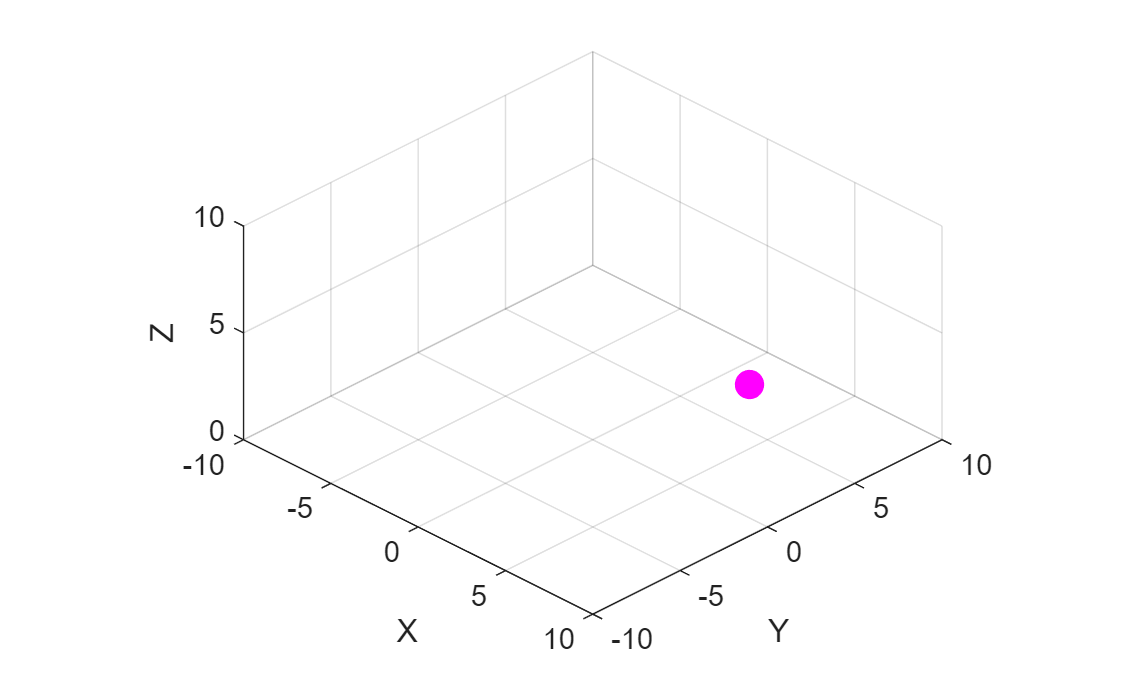

    3.0000    0.6747    6.4031



figure



[z, theta, r, isValid] = ik_cylindrical(5, 4, 3);
if isValid
    plot_robot(z, theta, r);
    disp([z, theta, r])
end


function [z, theta, r, isValid] = ik_cylindrical(x, y, z)

    r = sqrt(x^2 + y^2);
    theta = atan2(y, x);   % range (-pi, pi)


    z_lim     = [0, 10];
    theta_lim = [-pi, pi];
    r_lim     = [2, 8];


    isValid = ...
        z >= z_lim(1)     && z <= z_lim(2) && ...
        theta >= theta_lim(1) && theta <= theta_lim(2) && ...
        r >= r_lim(1)     && r <= r_lim(2);

    if ~isValid
        warning('Target position is outside robot workspace');
    end
end

